Maximum current: 2.021


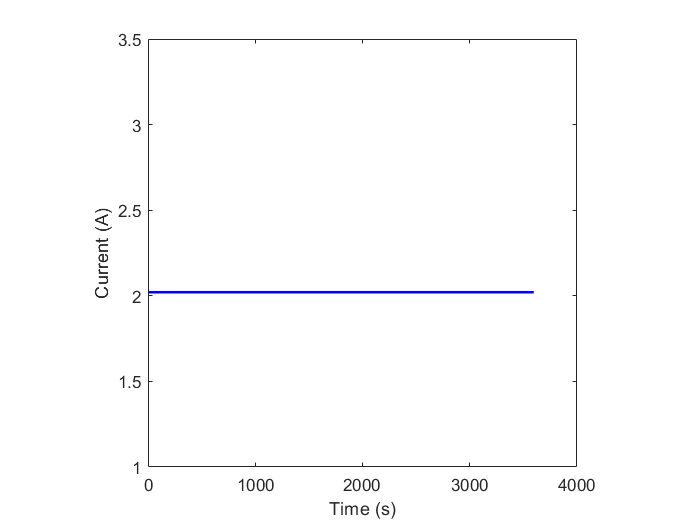

t=432.00
  States:
    Tb = 333.477 K
    Vo = 0.236892 V
    Vsn = 0.0306928 V
    Vsp = 0.00335294 V
    qnB = 6077.15 C
    qnS = 649.775 C
    qpB = 5322.85 C
    qpS = 616.892 C
  Inputs:
    P = 2.021 W
  Outputs:
    Tbm = 60.3265 degrees C
    Vm = 3.76796 V
t=864.00
  States:
    Tb = 333.613 K
    Vo = 0.236892 V
    Vsn = 0.050608 V
    Vsp = 0.00314989 V
    qnB = 5291.39 C
    qnS = 562.467 C
    qpB = 6108.61 C
    qpS = 704.199 C
  Inputs:
    P = 2.021 W
  Outputs:
    Tbm = 60.4635 degrees C
    Vm = 3.66546 V
t=1296.00
  States:
    Tb = 333.692 K
    Vo = 0.236892 V
    Vsn = 0.0638534 V
    Vsp = 0.00298191 V
    qnB = 4505.62 C
    qnS = 475.16 C
    qpB = 6894.38 C
    qpS = 791.506 C
  Inputs:
    P = 2.021 W
  Outputs:
    Tbm = 60.5423 degrees C
    Vm = 3.59137 V
t=1728.00
  States:
    Tb = 333.747 K
    Vo = 0.236892 V
    Vsn = 0.0731615 V
    Vsp = 0.0028405 V
    qnB = 3719.86 C
    qnS = 387.853 C
    qpB = 7680.14 C
    qpS = 878.814 C
  Inputs:
    P =

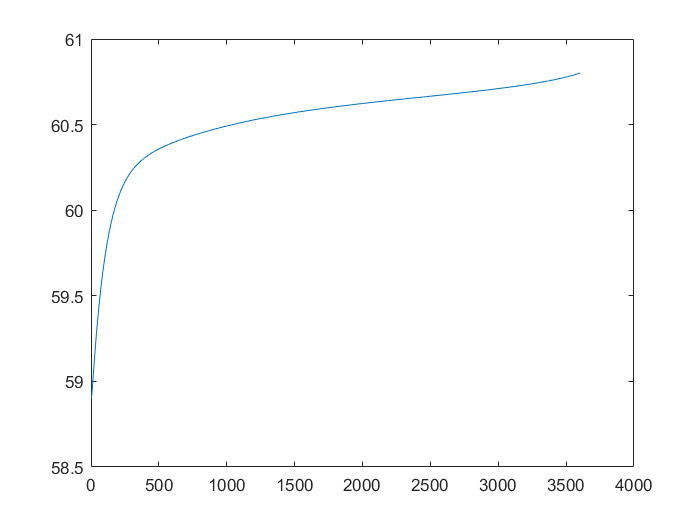

 
-------- Final Results --------
 
Discharge time: 3601 s
Discharge temperature: 60.801 degC
Ambient temperature: 58.9 degC
 
-------- End of final results --------
 
Time: 60 s
    Tbm = 59.4494 degrees C
    Vm = 3.89584 V
    EOD: 3592.66 s


Time: 120 s
    Tbm = 59.8138 degrees C
    Vm = 3.87328 V
    EOD: 3782.26 s


Time: 180 s
    Tbm = 60.0244 degrees C
    Vm = 3.8508 V
    EOD: 3710.09 s


Time: 240 s
    Tbm = 60.1503 degrees C
    Vm = 3.83069 V
    EOD: 3666 s


Time: 300 s
    Tbm = 60.229 degrees C
    Vm = 3.80886 V
    EOD: 3744.05 s


Time: 360 s
    Tbm = 60.282 degrees C
    Vm = 3.78877 V
    EOD: 3595.25 s


Time: 420 s
    Tbm = 60.3197 degrees C
    Vm = 3.77118 V
    EOD: 3709.76 s


Time: 480 s
    Tbm = 60.3503 degrees C
    Vm = 3.75469 V
    EOD: 3631.7 s


Time: 540 s
    Tbm = 60.3749 degrees C
    Vm = 3.73886 V
    EOD: 3714.95 s


Time: 600 s
    Tbm = 60.3923 degrees C
    Vm = 3.72353 V
    EOD: 3751.58 s


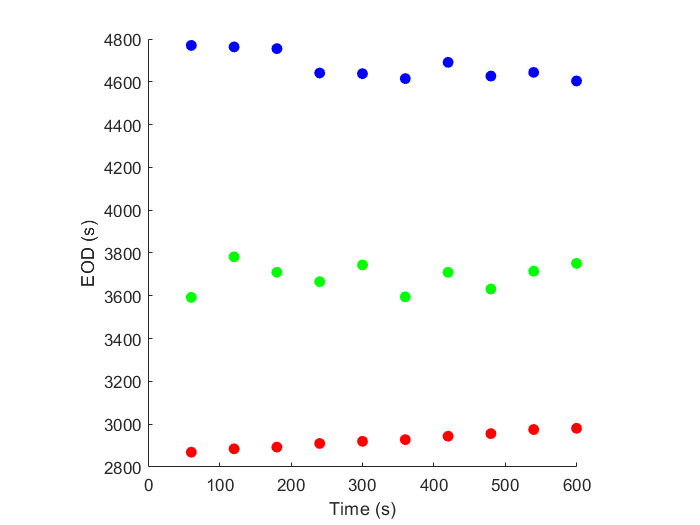

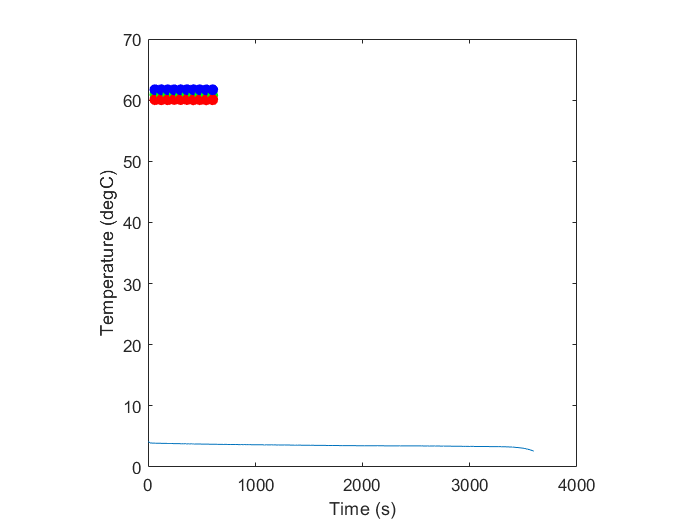

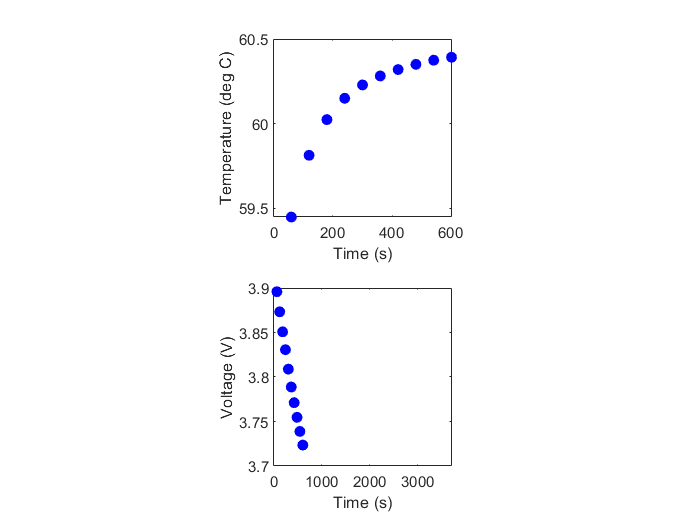

% 1C simulation
clf;
oneC = 2.021; %Default value
crate = 1;
loadval = oneC.*crate;
loads = [loadval;3600];
% loads = [4.2; 100*36];
horizon = 5000;
numSamples = 100;
simresults = testPrognoser(loads,horizon,numSamples);

plot(simresults.time,simresults.voltage)

oneC = 2.025; %Default value
crate = 1;
trueEODinHr = 1;
loadval = oneC.*crate;
% loads = [loadval;3600];
loads = [4.2; 100*60];
horizon = 6000;
numSamples = 50;


battery = Battery.Create;
oneC = 2.1; %Default value
cratio= loads(1)./oneC;
trueEOD = 3600./cratio;
trueEODinHr = trueEOD./3600;
loadval = oneC./trueEODinHr;
fprintf('Maximum current: %g\n',loadval);
figure(1);
plot([0;cumsum(loads(2:2:end))],[loads(1);loads(1:2:end-1)],'-','LineWidth',1.5,'Color','blue');
xlabel('Time (s)');
ylabel('Current (A)');
axis square
box on
ax = gca;
ax.Color = 'None';

battery.inputEqnHandle = @(P,t)Battery.InputEqn(P,t,loads);
[Ttosim,~,~,Z] = battery.simulateToThreshold('printTime','60');
trueEOD = Ttosim(end);
figure(2)
plot(Ttosim,loads(1)./Z(2,:))
figure(2)
plot(Ttosim,Z(2,:))

% figure(3)
plot(Ttosim,Z(1,:))
% endTemp = Z(1,end);
% % disp(' ')
% disp('-------- Final Results --------')
disp(' ')
fprintf('Discharge time: %g s\nDischarge temperature: %g degC\n',Ttosim(end),endTemp);
fprintf('Ambient temperature: %g degC\n',battery.P.x0.Tb-273.15);
disp(' ')
disp('-------- End of final results --------')
disp(' ')